**3.1 Stage 1: Basic implementation: Image compression**

3.1.1 Implementation of a basic image coding system which comprise of the block diagrams show in Fig 1, with 3 level of quantisation values. 

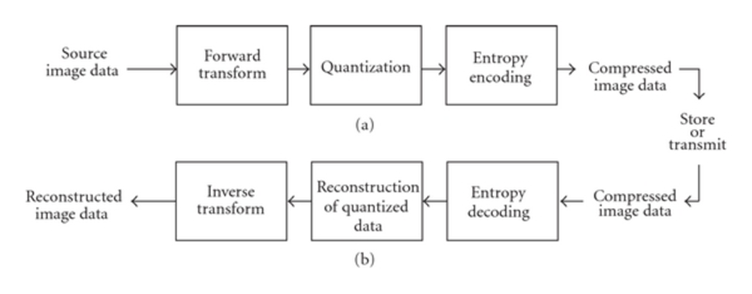

**1. Choose the transform**

Use the block-based 2D DCT (This is  the JPEG and H.26x use). Split the image into non-overlapping 8×8 blocks and then apply `dct2` to each. 

This is  the Forward transform  block.

**2. Choose the quantization scheme**

Use the standard JPEG luminance quantization matrix `Q50`, scaled by a quality factor `QF`:

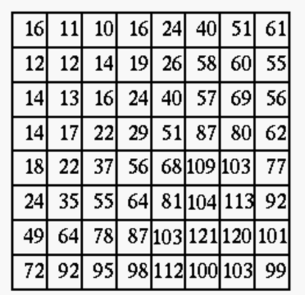

- `QF` low (e.g. 10) → coarse quantization → smaller file, lower quality

- `QF` medium (e.g. 50) → baseline matrix

- `QF` high (e.g. 90) → fine quantization → larger file, higher quality

**3. Entropy encoding**

After quantization, most high-frequency coefficients become zero. 

Then, do

- Zigzag scan each 8×8 block (converts 2D matrix  into 1D vector, grouping zeros together)

- Run-length encode the zeros

- Huffman-encode the resulting symbols.

**4. Decoder (mirror path)**

Entropy decode → de-zigzag → dequantize (multiply back by same Q matrix) → inverse DCT (`idct2`) → reassemble blocks → reconstructed image.

**5. Evaluate**

For each of the 3 QP levels compute:

- Compression ratio (original bits / compressed bits)

- PSNR (original vs reconstructed)

- Visual comparison

clear; clc; close all;

%% Defining settings
img_path   = 'image1 (1).jpg';     % < relative image path
% used 8x8 block size
block_size = 8;                
% Quality factors defining the 3 quantisation levels (0-100 scale, JPEG convention)
QF_low    = 10;    % coarse quantisation ,low quality, high compression
QF_medium = 50;    % baseline quantisation matrix
QF_high   = 90;    % fine quantisation ,high quality, low compression

QFs = [QF_low, QF_medium, QF_high];
labels = {'LOW quality (QF=10)', 'MEDIUM quality (QF=50)', 'HIGH quality (QF=90)'};

%% 1.Load and pre-processing the image
I_rgb = imread(img_path);
% Convert RGB image into gray scale image
I_gray = rgb2gray(I_rgb);         
I_gray = double(I_gray);

[H, W] = size(I_gray);

% Pad image so dimensions are multiples of block_size
padH = mod(block_size - mod(H, block_size), block_size); %calculting the PadH
padW = mod(block_size - mod(W, block_size), block_size); %calculting the PadW
I_pad = padarray(I_gray, [padH padW], 'replicate', 'post');
[Hp, Wp] = size(I_pad);

fprintf('Original image size: %d x %d\n', H, W);

Original image size: 2373 x 3583


fprintf('Padded image size  : %d x %d\n', Hp, Wp);

Padded image size  : 2376 x 3584


%% 2. Stadard JPEG luminance matrix (Q- matrix)
Q50 = [16 11 10 16 24  40  51  61;
       12 12 14 19 26  58  60  55;
       14 13 16 24 40  57  69  56;
       14 17 22 29 51  87  80  62;
       18 22 37 56 68  109 103 77;
       24 35 55 64 81  104 113 92;
       49 64 78 87 103 121 120 101;
       72 92 95 98 112 100 103 99];

%% 3. zig zag scan (8x8)
zigzagIdx = zigzagIndices(block_size);

%% 4 Loop for the 3 qunatization levels.
results = struct();

for k = 1:length(QFs)
    QF = QFs(k);
    Qmat = buildQuantMatrix(Q50, QF);   % scale Q50 by quality factor

    %% Encoder side
    % (a) Forward Transform: block DCT
    % (b) Quantization
    % (c) Entropy Encoding (zigzag + RLE + Huffman)
    [bitstream, huffDict, blockDims, symbolStream] = encodeImage(I_pad, Qmat, block_size, zigzagIdx);

    compressed_bits = numel(bitstream);
    original_bits   = numel(I_gray) * 8;   % 8 bits/pixel original
    compression_ratio = original_bits / compressed_bits;

    %% Decoder side
    % (a) Entropy Decoding
    % (b) Reconstruction of quantised data (inverse zigzag + dequantise)
    % (c) Inverse Transform
    I_rec_pad = decodeImage(bitstream, huffDict, Qmat, block_size, zigzagIdx, blockDims);

    % Remove padding to compare against the original
    I_rec = I_rec_pad(1:H, 1:W);
    I_rec = uint8(min(max(I_rec, 0), 255));

    %% METRICS
    psnr_val = psnrCalc(uint8(I_gray(1:H,1:W)), I_rec);

    fprintf('\n--- %s ---\n', labels{k});
    fprintf('Compressed size     : %.1f kbits (%.2f KB)\n', compressed_bits/1000, compressed_bits/8/1024);
    fprintf('Compression ratio   : %.2f : 1\n', compression_ratio);
    fprintf('PSNR                : %.2f dB\n', psnr_val);

    results(k).QF = QF;
    results(k).label = labels{k};
    results(k).compression_ratio = compression_ratio;
    results(k).psnr = psnr_val;
    results(k).reconstructed = I_rec;
    results(k).compressed_bits = compressed_bits;
end


--- LOW quality (QF=10) ---


Compressed size     : 2193.6 kbits (267.78 KB)


Compression ratio   : 31.01 : 1


PSNR                : 31.18 dB



--- MEDIUM quality (QF=50) ---


Compressed size     : 8461.5 kbits (1032.89 KB)


Compression ratio   : 8.04 : 1


PSNR                : 39.35 dB



--- HIGH quality (QF=90) ---


Compressed size     : 12304.7 kbits (1502.04 KB)


Compression ratio   : 5.53 : 1


PSNR                : 59.23 dB


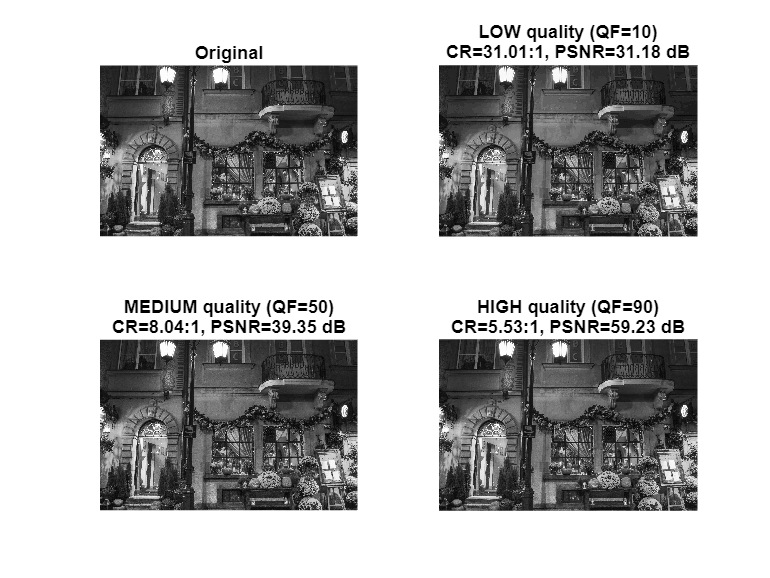


%%5.Results
figure('Name','Task 3.1.1 - Basic Image Codec Results');
subplot(2,2,1); imshow(uint8(I_gray)); title('Original');
for k = 1:3
    subplot(2,2,k+1);
    imshow(results(k).reconstructed);
    title(sprintf('%s\nCR=%.2f:1, PSNR=%.2f dB', results(k).label, ...
        results(k).compression_ratio, results(k).psnr));
end


% Summary table
fprintf('\n------------- SUMMARY -------------\n');


------------- SUMMARY -------------


fprintf('%-25s %-12s %-10s\n','Quality Level','CompRatio','PSNR(dB)');

Quality Level             CompRatio    PSNR(dB)  


for k = 1:3
    fprintf('%-25s %-12.2f %-10.2f\n', results(k).label, ...
        results(k).compression_ratio, results(k).psnr);
end

LOW quality (QF=10)       31.01        31.18     
MEDIUM quality (QF=50)    8.04         39.35     
HIGH quality (QF=90)      5.53         59.23     



%  LOCAL FUNCTIONS

function Qmat = buildQuantMatrix(Q50, QF)
% Scales the standard JPEG Q50 matrix to a given quality factor (1-100)
    if QF < 50
        S = 5000 / QF;
    else
        S = 200 - 2*QF;
    end
    Qmat = floor((S * Q50 + 50) / 100);
    Qmat(Qmat < 1)   = 1;
    Qmat(Qmat > 255) = 255;
end

function idx = zigzagIndices(N)
% Returns the linear indices (into an NxN matrix, column-major) in
% zigzag scan order, standard JPEG-style.
    M = zeros(N,N);
    val = 1;
    for s = 0:(2*N-2)
        if mod(s,2)==0
            r = min(s,N-1):-1:max(0,s-N+1);
            c = s - r;
        else
            c = min(s,N-1):-1:max(0,s-N+1);
            r = s - c;
        end
        for t = 1:length(r)
            M(r(t)+1, c(t)+1) = val;
            val = val + 1;
        end
    end
    [~, idx] = sort(M(:));
end

function [bitstream, huffDict, blockDims, symbolStream] = encodeImage(I_pad, Qmat, bs, zigzagIdx)
% ENCODER: forward DCT -> quantization -> zigzag -> RLE -> Huffman
    [Hp, Wp] = size(I_pad);
    nBR = Hp/bs; nBC = Wp/bs;
    blockDims = [nBR, nBC];

    I_shift = I_pad - 128;  % level shift, standard practice before DCT
    symbolStream = [];      % will hold RLE symbols: [runlength, level]

    for br = 1:nBR
        for bc = 1:nBC
            block = I_shift((br-1)*bs+1:br*bs, (bc-1)*bs+1:bc*bs);

            % (a) Forward Transform
            D = dct2(block);

            % (b) Quantization
            Qb = round(D ./ Qmat);

            % zigzag scan
            zz = Qb(zigzagIdx);

            % Run-length encode zeros: pairs (run-of-zeros, nonzero value)
            rle = runLengthEncode(zz);
            symbolStream = [symbolStream, rle]; %#ok<AGROW>
        end
    end

    % Huffman encode the full symbol stream
    [symbols, ~, ic] = unique(symbolStream);
    counts = accumarray(ic(:), 1);
    probs = counts / sum(counts);
    huffDict = huffmandict(symbols, probs);
    bitstream = huffmanenco(symbolStream, huffDict);
end

function I_rec = decodeImage(bitstream, huffDict, Qmat, bs, zigzagIdx, blockDims)
% DECODER: Huffman decode -> inverse RLE -> inverse zigzag ->
%          dequantize -> inverse DCT -> reassemble image
    nBR = blockDims(1); nBC = blockDims(2);
    Hp = nBR*bs; Wp = nBC*bs;

    symbolStream = huffmandeco(bitstream, huffDict);
    I_rec = zeros(Hp, Wp);

    ptr = 1;

    for br = 1:nBR
        for bc = 1:nBC
            [zz, ptr] = runLengthDecode(symbolStream, ptr, bs*bs);
            Qb = zeros(bs,bs);
            Qb(zigzagIdx) = zz;

            % dequantize
            D = Qb .* Qmat;

            % inverse transform
            block = idct2(D) + 128;

            I_rec((br-1)*bs+1:br*bs, (bc-1)*bs+1:bc*bs) = block;
        end
    end
end

function rle = runLengthEncode(zz)
% Encodes a 1D vector as (run-of-zeros, value) pairs. A final (0,0)
% marker denotes "end of block" (all remaining coefficients are zero) -
% this mirrors JPEG's EOB symbol.
    rle = [];
    run = 0;
    N = length(zz);
    lastNZ = find(zz~=0, 1, 'last');
    if isempty(lastNZ)
        rle = [0, 0]; % whole block is zero -> EOB immediately
        return;
    end
    for i = 1:lastNZ
        if zz(i) == 0
            run = run + 1;
        else
            rle = [rle, run, zz(i)]; %#ok<AGROW>
            run = 0;
        end
    end
    rle = [rle, 0, 0]; % EOB marker
end

function [zz, ptr] = runLengthDecode(symbolStream, ptr, blockLen)
    zz = zeros(1, blockLen);
    pos = 1;
    while true
        run = symbolStream(ptr);
        val = symbolStream(ptr+1);
        ptr = ptr + 2;
        if run == 0 && val == 0
            break; % EOB
        end
        pos = pos + run;
        zz(pos) = val;
        pos = pos + 1;
    end
end

function p = psnrCalc(orig, rec)
    orig = double(orig); rec = double(rec);
    mse = mean((orig(:)-rec(:)).^2);
    if mse == 0
        p = Inf;
    else
        p = 10*log10(255^2/mse);
    end
end

3.1.2  Adjust the compression ratio of your image encoder to meet the following bit rates. Assume that you will be transmitting one image per second and the output should be at the best possible PSNR value. (Marks  10%)

Bit rate of the channel =  608 kbps

%% 3.1.2
%  Meet channel bit-rate with best PSNR
%  One image/sec -> each image must be <= 608,000 bits.
%  Method: spatial downsampling + QF sweep -> highest QF that still fits.
clear; clc; close all;

%% Settings
img_path    = 'image1 (1).jpg';
block_size  = 8;
TARGET_BITS = 608 * 1000;              % 608 kbps budget per image

%% Load (same preprocessing as 3.1.1)
I_rgb  = imread(img_path);
I_gray = double(rgb2gray(I_rgb));
[H, W] = size(I_gray);
Q50 = [16 11 10 16 24  40  51  61;
       12 12 14 19 26  58  60  55;
       14 13 16 24 40  57  69  56;
       14 17 22 29 51  87  80  62;
       18 22 37 56 68  109 103 77;
       24 35 55 64 81  104 113 92;
       49 64 78 87 103 121 120 101;
       72 92 95 98 112 100 103 99];
zigzagIdx = zigzagIndices(block_size);

%% Downsampling factors to test
dsFactors = [1.5 1.75 2.0 2.25 2.5 3.0];
results = struct();

for i = 1:numel(dsFactors)
    ds = dsFactors(i);

    % 1) Spatial downsampling
    I_ds     = imresize(I_gray, 1/ds, 'bilinear');
    padH = mod(block_size - mod(size(I_ds,1), block_size), block_size);
    padW = mod(block_size - mod(size(I_ds,2), block_size), block_size);
    I_ds_pad = padarray(I_ds, [padH padW], 'replicate', 'post');
    [Hp, Wp] = size(I_ds_pad);

    % 2) Binary-search the highest QF whose bitstream fits in TARGET_BITS
    lo = 1; hi = 100; QF_best = 1; bits = inf;
    while lo <= hi
        qf = round((lo+hi)/2);
        Qmat = buildQuantMatrix(Q50, qf);
        [bstream, ~, bdims, ~] = encodeImage(I_ds_pad, Qmat, block_size, zigzagIdx);
        nb = numel(bstream);
        if nb <= TARGET_BITS
            QF_best = qf; bits = nb; lo = qf + 1;   % fits -> try finer
        else
            hi = qf - 1;                             % too big -> coarser
        end
    end

    % 3) Decode at best QF, upsample back, compute PSNR vs original
    Qmat = buildQuantMatrix(Q50, QF_best);
    [bstream, huffDict, bdims, ~] = encodeImage(I_ds_pad, Qmat, block_size, zigzagIdx);
    bits = numel(bstream);
    I_rec_pad = decodeImage(bstream, huffDict, Qmat, block_size, zigzagIdx, bdims);
    I_rec_low = I_rec_pad(1:size(I_ds,1), 1:size(I_ds,2));
    I_rec     = uint8(min(max(imresize(I_rec_low, [H W], 'bilinear'),0),255));
    psnr_val  = psnrCalc(uint8(I_gray), I_rec);

    results(i).factor = ds;
    results(i).QF     = QF_best;
    results(i).bits   = bits;
    results(i).psnr   = psnr_val;
    results(i).rec    = I_rec;

    fprintf('DS=%4.2f  QF=%3d  %8.1f kbps  PSNR=%.2f dB\n', ds, QF_best, bits/1000, psnr_val);
end

DS=1.50  QF=  4     581.7 kbps  PSNR=25.96 dB
DS=1.75  QF=  6     599.6 kbps  PSNR=26.94 dB
DS=2.00  QF=  8     584.4 kbps  PSNR=27.03 dB
DS=2.25  QF= 11     603.1 kbps  PSNR=27.39 dB
DS=2.50  QF= 14     596.0 kbps  PSNR=26.15 dB
DS=3.00  QF= 22     601.0 kbps  PSNR=27.05 dB



%% Pick the factor under budget with the best PSNR
validIdx = find([results.bits] <= TARGET_BITS);
[~, k]   = max([results(validIdx).psnr]);
best     = results(validIdx(k));

fprintf('\n================ SWEET SPOT ================\n');


================ SWEET SPOT ================


fprintf('Downsampling factor : %4.2f\n', best.factor);

Downsampling factor : 2.25


fprintf('Best Quality Factor  : %d\n',   best.QF);

Best Quality Factor  : 11


fprintf('Bit-rate achieved    : %.2f kbps  (target 608 kbps)\n', best.bits/1000);

Bit-rate achieved    : 603.09 kbps  (target 608 kbps)


fprintf('Budget utilisation   : %.1f %%\n', best.bits/TARGET_BITS*100);

Budget utilisation   : 99.2 %


fprintf('Best PSNR            : %.2f dB\n',  best.psnr);

Best PSNR            : 27.39 dB


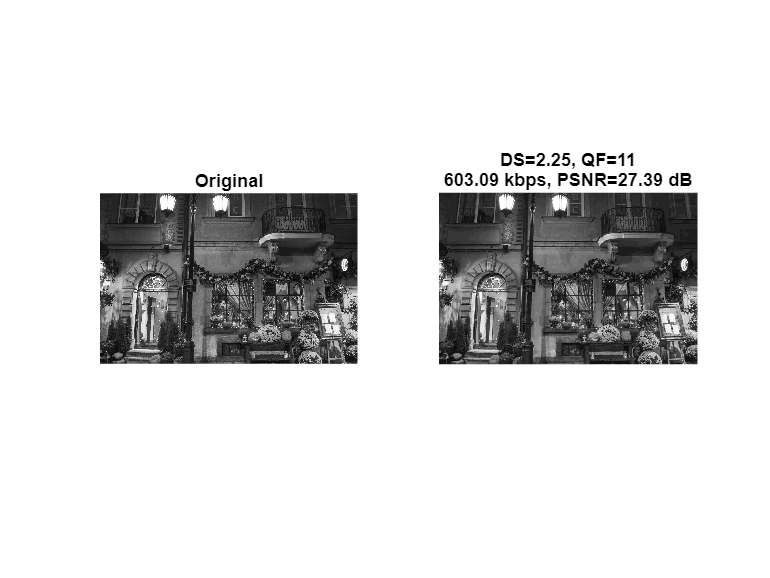


%% Display
figure('Name','3.1.2 - Best PSNR at 608 kbps');
subplot(1,2,1); imshow(uint8(I_gray)); title('Original');
subplot(1,2,2); imshow(best.rec);
title(sprintf('DS=%.2f, QF=%d\n%.2f kbps, PSNR=%.2f dB', ...
              best.factor, best.QF, best.bits/1000, best.psnr));

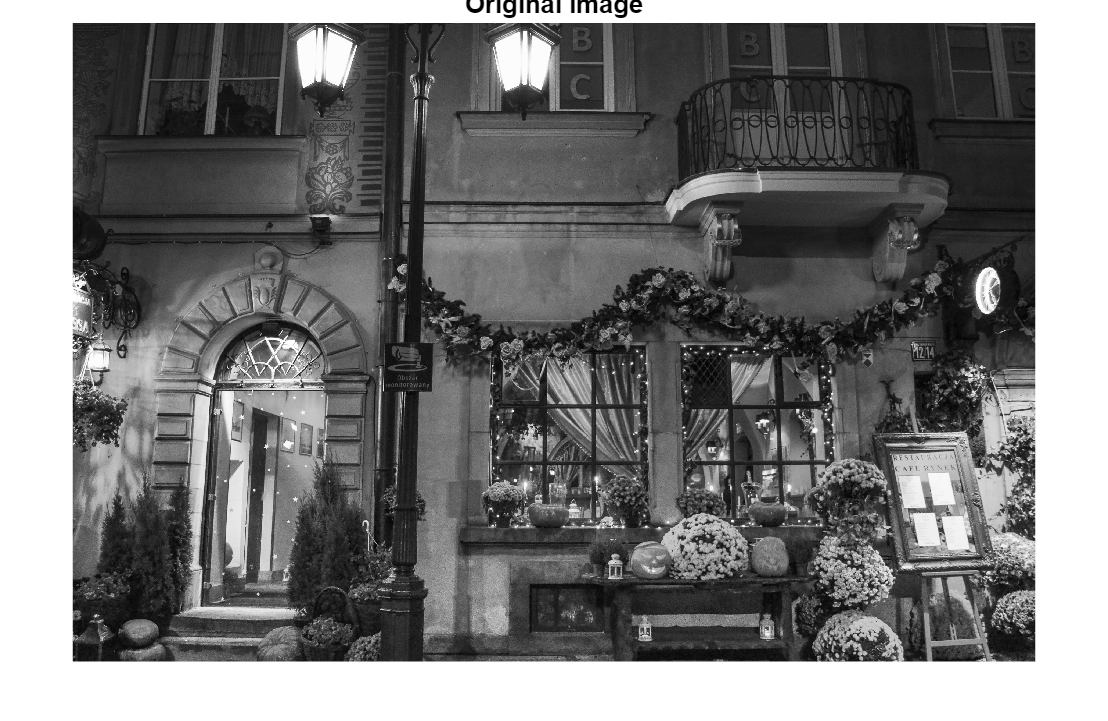


%% Display original and compressed in large separate figures
% Original
figure('Name','Original image','Color','w','Position',[60 60 900 700]);
imshow(uint8(I_gray)); title('Original image','FontSize',14);

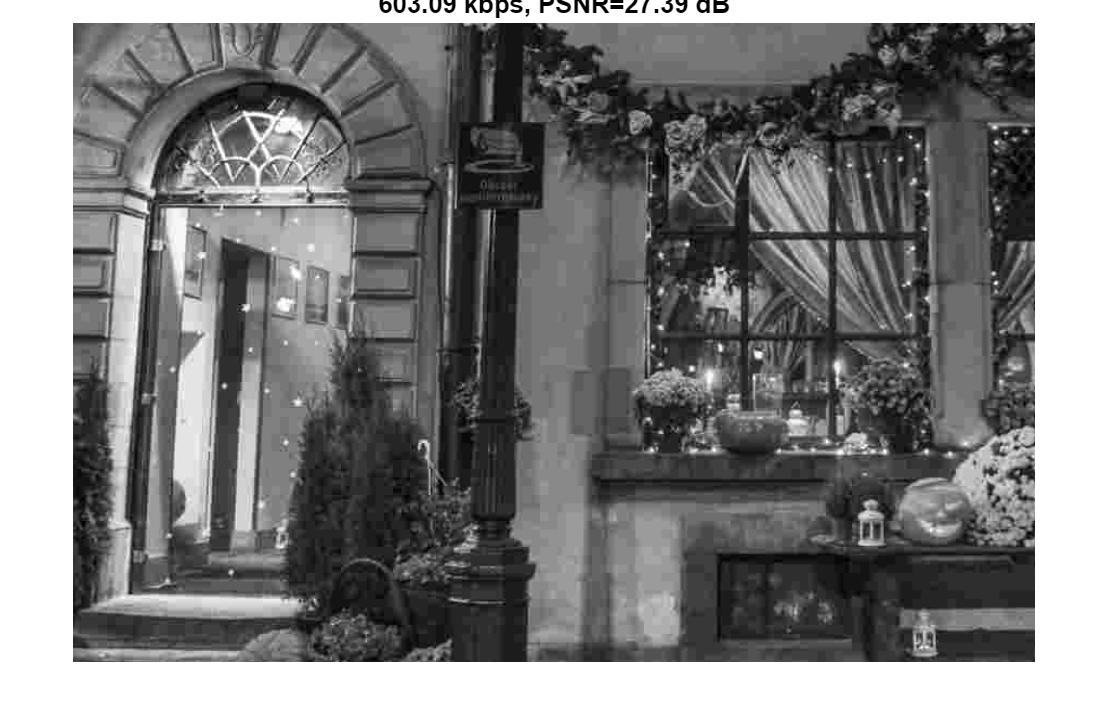


% Compressed (best PSNR at 608 kbps)
figure('Name','Compressed @608 kbps','Color','w','Position',[990 60 900 700]);
imshow(best.rec); 
title(sprintf('Compressed - DS=%.2f, QF=%d\n%.2f kbps, PSNR=%.2f dB', ...
              best.factor, best.QF, best.bits/1000, best.psnr), 'FontSize',14);

3.1.3 Implement an algorithm where output of your image compression can adopt to any given bitrate.  

%% 3.1.3 Adaptive Bitrate Algorithm
% Implement an algorithm where the output of the image compression 
% can adapt to ANY given bitrate while maximizing PSNR.

clear; clc; close all;

%% 1. Initialization and Setup
img_path = 'image1 (1).jpg';
block_size = 8;

I_rgb = imread(img_path);
I_gray = double(rgb2gray(I_rgb));
[H, W] = size(I_gray);

Q50 = [16 11 10 16 24 40 51 61;
       12 12 14 19 26 58 60 55;
       14 13 16 24 40 57 69 56;
       14 17 22 29 51 87 80 62;
       18 22 37 56 68 109 103 77;
       24 35 55 64 81 104 113 92;
       49 64 78 87 103 121 120 101;
       72 92 95 98 112 100 103 99];

zigzagIdx = zigzagIndices(block_size);

%% 2. Test the Adaptive Algorithm with Multiple Bitrates
% We will test a low, medium (your specific target), and high bitrate
test_targets = [200, 608, 1200]; % Target bitrates in kbps
results_313 = struct();

fprintf('\n================ 3.1.3 ADAPTIVE CODEC TEST ================\n');


================ 3.1.3 ADAPTIVE CODEC TEST ================



for i = 1:length(test_targets)
    target = test_targets(i);
    fprintf('\n---> Requesting Target Bitrate: %d kbps\n', target);
    
    % Call the newly built adaptive algorithm function
    [I_opt, actual_kbps, max_psnr, best_ds, best_qf] = adaptiveImageCodec(I_gray, target, Q50, block_size, zigzagIdx);
    
    % Store results for plotting
    results_313(i).target = target;
    results_313(i).actual = actual_kbps;
    results_313(i).psnr = max_psnr;
    results_313(i).ds = best_ds;
    results_313(i).qf = best_qf;
    results_313(i).img = I_opt;
    
    fprintf('     ACHIEVED: %.2f kbps | PSNR: %.2f dB (DS: %.2f, QF: %d)\n', actual_kbps, max_psnr, best_ds, best_qf);
end


---> Requesting Target Bitrate: 200 kbps


     ACHIEVED: 199.92 kbps | PSNR: 24.36 dB (DS: 5.00, QF: 16)



---> Requesting Target Bitrate: 608 kbps


     ACHIEVED: 603.09 kbps | PSNR: 27.39 dB (DS: 2.25, QF: 11)



---> Requesting Target Bitrate: 1200 kbps


     ACHIEVED: 1172.50 kbps | PSNR: 29.85 dB (DS: 1.50, QF: 11)


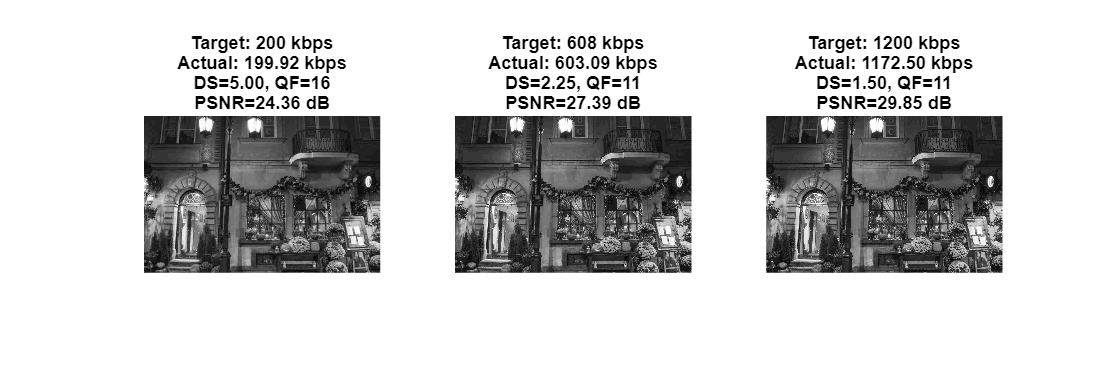


%% 3. Display Adaptive Results
figure('Name', '3.1.3 Adaptive Bitrate Algorithm Results', 'Color', 'w', 'Position', [100 100 1200 400]);

for i = 1:length(test_targets)
    subplot(1, length(test_targets), i);
    imshow(results_313(i).img);
    title(sprintf('Target: %d kbps\nActual: %.2f kbps\nDS=%.2f, QF=%d\nPSNR=%.2f dB', ...
        results_313(i).target, results_313(i).actual, results_313(i).ds, results_313(i).qf, results_313(i).psnr));
end


%% ================== CORE ADAPTIVE FUNCTION ==================
function [I_opt, actual_kbps, max_psnr, best_ds, best_qf] = adaptiveImageCodec(I_original, target_kbps, Q50, block_size, zigzagIdx)
    % This function scales the image and tests QFs to hit any target bitrate
    target_bits = target_kbps * 1000;
    [H, W] = size(I_original);
    
    % Expanded range to handle extremely low or extremely high target bitrates
    dsFactors = [1.0, 1.25, 1.5, 1.75, 2.0, 2.25, 2.5, 3.0, 4.0, 5.0];
    
    best_psnr = -1;
    best_ds = 1;
    best_qf = 1;
    best_bits = inf;
    I_opt = uint8(zeros(H, W)); 
    
    for ds = dsFactors
        % 1. Spatial Downsampling
        I_ds = imresize(I_original, 1/ds, 'bilinear');
        padH = mod(block_size - mod(size(I_ds, 1), block_size), block_size);
        padW = mod(block_size - mod(size(I_ds, 2), block_size), block_size);
        I_ds_pad = padarray(I_ds, [padH padW], 'replicate', 'post');
        
        % 2. Binary Search for QF
        lo = 1; hi = 100; qf_best = -1; bits_best = inf;
        
        while lo <= hi
            qf = floor((lo + hi) / 2);
            Qmat = buildQuantMatrix(Q50, qf);
            [bstream, ~, ~, ~] = encodeImage(I_ds_pad, Qmat, block_size, zigzagIdx);
            nb = numel(bstream);
            
            if nb <= target_bits
                qf_best = qf;
                bits_best = nb;
                lo = qf + 1; % Fits budget, try a higher quality factor
            else
                hi = qf - 1; % Exceeds budget, decrease quality
            end
        end
        
        % 3. Evaluate PSNR if a valid configuration was found
        if qf_best ~= -1
            Qmat = buildQuantMatrix(Q50, qf_best);
            [bstream, huffDict, bdims, ~] = encodeImage(I_ds_pad, Qmat, block_size, zigzagIdx);
            
            I_rec_pad = decodeImage(bstream, huffDict, Qmat, block_size, zigzagIdx, bdims);
            I_rec_low = I_rec_pad(1:size(I_ds, 1), 1:size(I_ds, 2));
            
            % Upsample back to original size for PSNR calculation
            I_rec_up = imresize(I_rec_low, [H W], 'bilinear');
            I_rec_up = uint8(min(max(I_rec_up, 0), 255));
            
            current_psnr = psnrCalc(uint8(I_original), double(I_rec_up));
            
            % Save if it is the highest PSNR achieved across all tested Downsampling scales
            if current_psnr > best_psnr
                best_psnr = current_psnr;
                best_ds = ds;
                best_qf = qf_best;
                best_bits = bits_best;
                I_opt = I_rec_up;
            end
        end
    end
    
    actual_kbps = best_bits / 1000;
    max_psnr = best_psnr;
end

% (Make sure all your previous Local Functions are still at the bottom of the script: 
% buildQuantMatrix, zigzagIndices, encodeImage, decodeImage, runLengthEncode, 
% runLengthDecode, and psnrCalc)